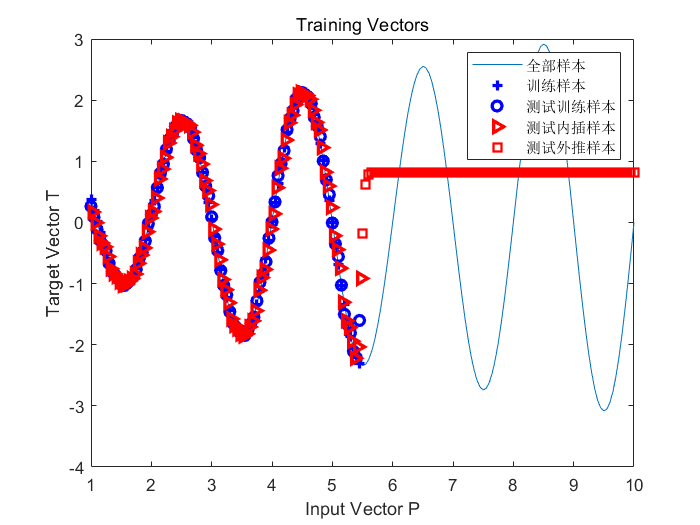

clf;
rng(5);
rng;
%设定目标函数值
P = 1:.05:10;
T = exp(-P)+(P.^0.5).*sin(pi*P);
train_d = P(1:90);              %训练用数据
train_l = T(1:90);              %训练用label
trian_iner_d = 1.025:.05:5.5;   %内插测试数据
test_extra = P(91:181);         %外推测试数据
%设置训练超参数
maxiter = 2000;         %最大迭代次数
eta = 0.01;              %学习率
mc = 0.8;               %动量因子
eb = 0;              %误差容限度
nHi = 30;                % 隐藏层数目
%建立网络
net.trainParam.epochs = maxiter;
net.trainParam.goal = eb;
net.trainParam.lr = eta;
net.trainParam.mc = mc;
net=feedforwardnet(nHi, 'trainbfg');
%训练隐藏层数目为5的网络
[net,tr] = train(net, train_d, train_l);
train_out = sim(net, train_d);
trian_inter_out = sim(net, trian_iner_d);
test_extra_out = sim(net, test_extra);

plot(P,T);
hold on;
plot(train_d, train_l,'+','MarkerEdgeColor','b', 'LineWidth',2);
hold on;
plot(train_d,train_out,'o', 'MarkerEdgeColor','b', 'LineWidth',2);
hold on;
plot(trian_iner_d, trian_inter_out,'>','MarkerEdgeColor','r', 'LineWidth',2);
hold on;
plot(test_extra, test_extra_out,'s','MarkerEdgeColor','r', 'LineWidth',2);
legend('全部样本', '训练样本', '测试训练样本', '测试内插样本', '测试外推样本');
title('Training Vectors');
xlabel('Input Vector P');
ylabel('Target Vector T');


%结果分析
%对于给定函数的拟合，BP网络的训练结果只能实现对于给定训练集所包含的定义域范围内的准确推测，
%而对于远远超出训练集数据定义域的数据，BP网络将丧失推测能力。
%这进一步反映出了训练集数据分布的重要性，测试只能在同样的分布下体现出良好效果。